# Solar array Thuwal Building 3

Description: This algorithm plot the capacity factor, energy yield, variation of values for the solar array. 

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 11/2021

clc
clear 
close all

% Load data
load B3PVKW.mat

## Organize Data

Nom_Cap=1012.632; %[kW]
Date = B3PVKW.historyUN2400_EXTPV_kW;
Time = B3PVKW.VarName2;

Date.Format = 'dd.MM.uuuu HH:mm';
Time.Format = 'dd.MM.uuuu HH:mm';

myDatetime = Date + timeofday(Time);

T=timetable(myDatetime,B3PVKW.VarName5);

% Apply retime function to obtain daily/monthly mean
TdailyMean = retime(T,'daily','mean');
TweeklyMean = retime(T,'weekly','mean');
TmonthlyMean = retime(T,'monthly','mean');
TyearlyMean = retime(T,'yearly','mean');

TmonthlyMax =retime(T,'monthly','max');
TmonthlyMin =retime(T,'monthly','min');

% Get mean value
% Mean Day Week Month
M_D_W_M_18_19=[nanmean(TdailyMean.Var1(1:366)) nanmean(TweeklyMean.Var1(1:53)) nanmean(TmonthlyMean.Var1(1:12))]

M_D_W_M_18_19 =   143.4806  143.7310  143.2946


Y_18_19=mean(M_D_W_M_18_19)

Y_18_19 = 143.5021


M_D_W_M_19_20=[nanmean(TdailyMean.Var1(367:732))  nanmean(TweeklyMean.Var1(54:106)) nanmean(TmonthlyMean.Var1(13:24))]

M_D_W_M_19_20 =   122.6458  122.6534  122.9908


Y_19_20=mean(M_D_W_M_18_19)

Y_19_20 = 143.5021


M_D_W_M_20_21=[nanmean(TdailyMean.Var1(733:1098)) nanmean(TweeklyMean.Var1(107:159)) nanmean(TmonthlyMean.Var1(25:36))]

M_D_W_M_20_21 =   131.2012  131.5228  132.1437


Y_20_21=mean(M_D_W_M_20_21)

Y_20_21 = 131.6226

## Figures Capacity Factor Mean

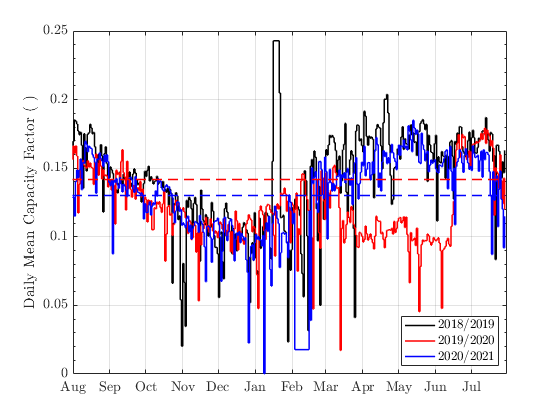

% Day
figure
stairs(TdailyMean.myDatetime(1:366),TdailyMean.Var1(1:366)/Nom_Cap,'k','LineWidth',1.5)
hold on
stairs(TdailyMean.myDatetime(1:366),TdailyMean.Var1(367:732)/Nom_Cap,'r','LineWidth',1.5)
stairs(TdailyMean.myDatetime(1:366),TdailyMean.Var1(733:1098)/Nom_Cap,'b','LineWidth',1.5)
stairs(TdailyMean.myDatetime([1 366]),[Y_18_19 Y_18_19]/Nom_Cap,'--k','LineWidth',1.5)
stairs(TdailyMean.myDatetime([1 366]),[Y_19_20 Y_19_20]/Nom_Cap,'--r','LineWidth',1.5)
stairs(TdailyMean.myDatetime([1 366]),[Y_20_21 Y_20_21]/Nom_Cap,'--b','LineWidth',1.5)
ylabel('Daily Mean Capacity Factor ( )','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('01-Aug-2018') datetime('31-Jul-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2018/2019','2019/2020','2020/2021','location','SE','interpreter','latex')

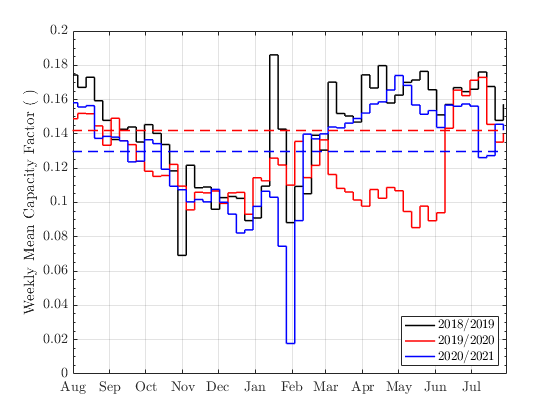

% print('-r400','-dpng','Day_B3.png')

% Week
figure
stairs(TweeklyMean.myDatetime(1:53),TweeklyMean.Var1(1:53)/Nom_Cap,'k','LineWidth',1.5)
hold on
stairs(TweeklyMean.myDatetime(1:53),TweeklyMean.Var1(54:106)/Nom_Cap,'r','LineWidth',1.5)
stairs(TweeklyMean.myDatetime(1:53),TweeklyMean.Var1(107:159)/Nom_Cap,'b','LineWidth',1.5)
stairs(TweeklyMean.myDatetime([1 53]),[Y_18_19 Y_18_19]/Nom_Cap,'--k','LineWidth',1.5)
stairs(TweeklyMean.myDatetime([1 53]),[Y_19_20 Y_19_20]/Nom_Cap,'--r','LineWidth',1.5)
stairs(TweeklyMean.myDatetime([1 53]),[Y_20_21 Y_20_21]/Nom_Cap,'--b','LineWidth',1.5)
ylabel('Weekly Mean Capacity Factor ( )','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('1-Aug-2018') datetime('31-Jul-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2018/2019','2019/2020','2020/2021','location','SE','interpreter','latex')

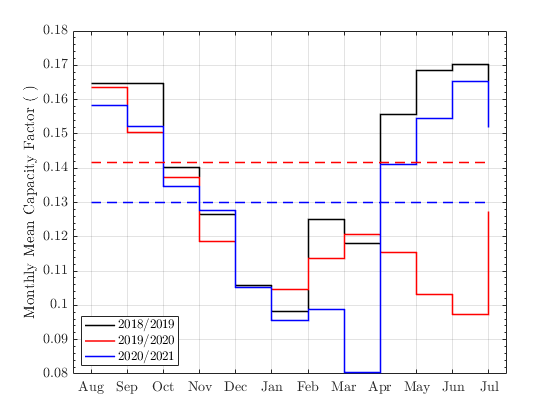

% print('-r400','-dpng','Week_B3.png')

% Month
Month=categorical({'Aug','Sep','Oct','Nov','Dec','Jan','Feb','Mar','Apr','May','Jun','Jul'});
figure
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1(1:12)/Nom_Cap,'k','Linewidth',1.5)
hold on
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1(13:24)/Nom_Cap,'r','Linewidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1(25:36)/Nom_Cap,'b','Linewidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),Y_18_19*ones(1,12)/Nom_Cap,'--k','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),Y_19_20*ones(1,12)/Nom_Cap,'--r','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),Y_20_21*ones(1,12)/Nom_Cap,'--b','LineWidth',1.5)
legend('2018/2019','2019/2020','2020/2021','location','SW','interpreter','latex')
ylabel('Monthly Mean Capacity Factor ( )','Interpreter','latex')
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-r400','-dpng','Month_B3.png')

## Figures: Capacity Factor Diff 

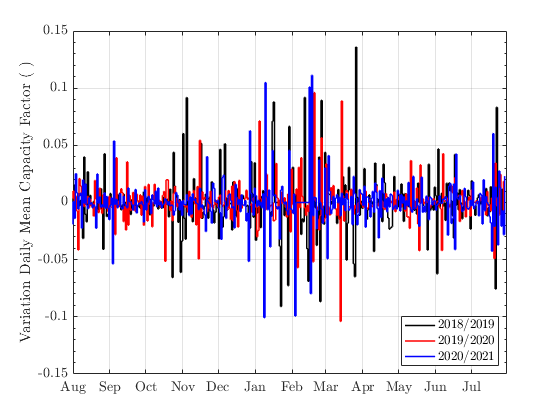

% Day
figure
stairs(TdailyMean.myDatetime(1:366),diff(TdailyMean.Var1([1 1:366]))/Nom_Cap,'k','LineWidth',1.5)
hold on
stairs(TdailyMean.myDatetime(1:366),diff(TdailyMean.Var1([367 367:732]))/Nom_Cap,'r','LineWidth',1.5)
stairs(TdailyMean.myDatetime(1:366),diff(TdailyMean.Var1([733 733:1098]))/Nom_Cap,'b','LineWidth',1.5)
ylabel('Variation Daily Mean Capacity Factor ( )','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('01-Aug-2018') datetime('31-Jul-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2018/2019','2019/2020','2020/2021','location','SE','interpreter','latex')

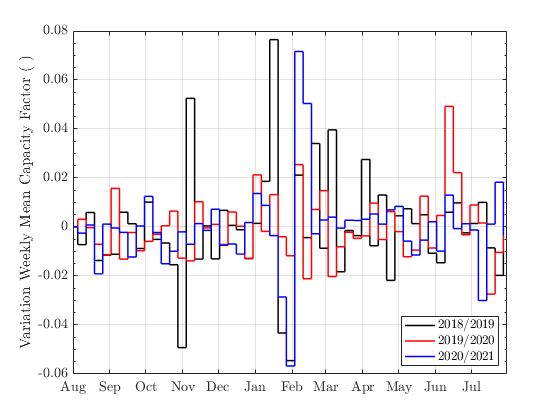

% print('-r400','-dpng','Dif_Day_B3.png')

% Week
figure
stairs(TweeklyMean.myDatetime(1:53),diff(TweeklyMean.Var1([1 1:53]))/Nom_Cap,'k','LineWidth',1.5)
hold on
stairs(TweeklyMean.myDatetime(1:53),diff(TweeklyMean.Var1([54 54:106]))/Nom_Cap,'r','LineWidth',1.5)
stairs(TweeklyMean.myDatetime(1:53),diff(TweeklyMean.Var1([107 107:159]))/Nom_Cap,'b','LineWidth',1.5)
ylabel('Variation Weekly Mean Capacity Factor ( )','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('01-Aug-2018') datetime('31-Jul-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2018/2019','2019/2020','2020/2021','location','SE','interpreter','latex')

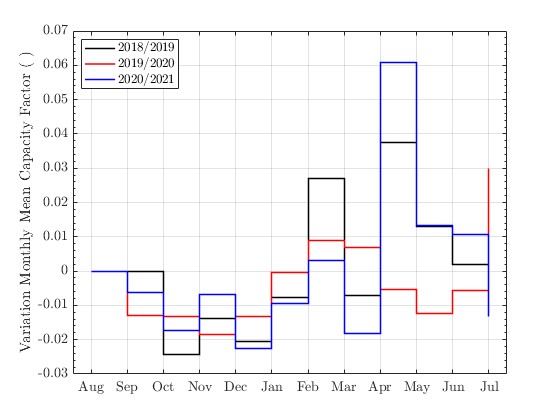

% print('-r400','-dpng','Dif_Week_B3.png')

% Month
figure
stairs(reordercats(Month,cellstr(Month)'),diff(TmonthlyMean.Var1([1 1:12]))/Nom_Cap,'k','Linewidth',1.5)
hold on
stairs(reordercats(Month,cellstr(Month)'),diff(TmonthlyMean.Var1([13 13:24]))/Nom_Cap,'r','Linewidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),diff(TmonthlyMean.Var1([25 25:36]))/Nom_Cap,'b','Linewidth',1.5)
legend('2018/2019','2019/2020','2020/2021','location','NW','interpreter','latex')
ylabel('Variation Monthly Mean Capacity Factor ( )','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-r400','-dpng','Dif_Month_B3.png')

## Figure Moving average 7 days

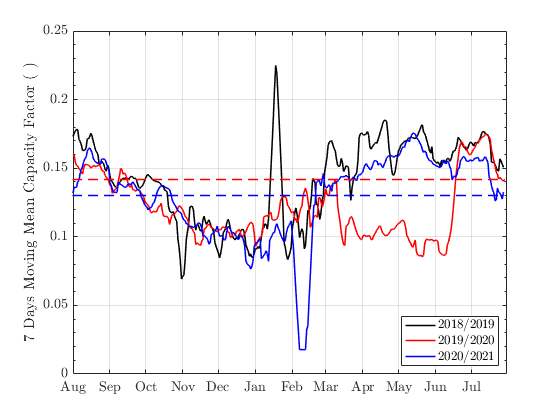

M1=movmean(TdailyMean.Var1(1:365),7)/Nom_Cap;
M2=movmean(TdailyMean.Var1(366:731),7)/Nom_Cap;
M3=movmean(TdailyMean.Var1(732:1096),7)/Nom_Cap;

figure
plot(TdailyMean.myDatetime(1:365),M1,'k','Linewidth',1.5)
hold on
plot(TdailyMean.myDatetime(1:366),M2,'r','Linewidth',1.5)
plot(TdailyMean.myDatetime(1:365),M3,'b','Linewidth',1.5)
stairs(TdailyMean.myDatetime([1 365]),Y_18_19*ones(1,2)/Nom_Cap,'--k','LineWidth',1.5)
stairs(TdailyMean.myDatetime([1 366]),Y_19_20*ones(1,2)/Nom_Cap,'--r','LineWidth',1.5)
stairs(TdailyMean.myDatetime([1 365]),Y_20_21*ones(1,2)/Nom_Cap,'--b','LineWidth',1.5)
legend('2018/2019','2019/2020','2020/2021','location','SE','interpreter','latex')
ylabel('7 Days Moving Mean Capacity Factor ( )','Interpreter','latex')
datetick('x','mmm')
% xlim([datetime('01-Aug-2018') datetime('31-Aug-2019')])
xlim([datetime('01-Aug-2018') datetime('31-Jul-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-r400','-dpng','Mov_mean_B3.png')


## Figures Energy Yield

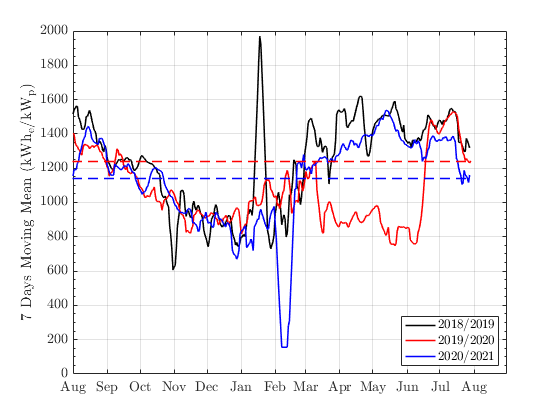

% Day
figure
plot(TdailyMean.myDatetime(1:365),M1*24*365,'k','Linewidth',1.5)
hold on
plot(TdailyMean.myDatetime(1:366),M2*24*365,'r','Linewidth',1.5)
plot(TdailyMean.myDatetime(1:365),M3*24*365,'b','Linewidth',1.5)
stairs(TdailyMean.myDatetime([1 365]),Y_18_19*ones(1,2)/Nom_Cap*24*365,'--k','LineWidth',1.5)
stairs(TdailyMean.myDatetime([1 366]),Y_19_20*ones(1,2)/Nom_Cap*24*365,'--r','LineWidth',1.5)
stairs(TdailyMean.myDatetime([1 365]),Y_20_21*ones(1,2)/Nom_Cap*24*365,'--b','LineWidth',1.5)
legend('2018/2019','2019/2020','2020/2021','location','SE','interpreter','latex')
ylabel('7 Days Moving Mean ($\mathrm{kWh_e/kW_p}$)','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('01-Aug-2018') datetime('31-Aug-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

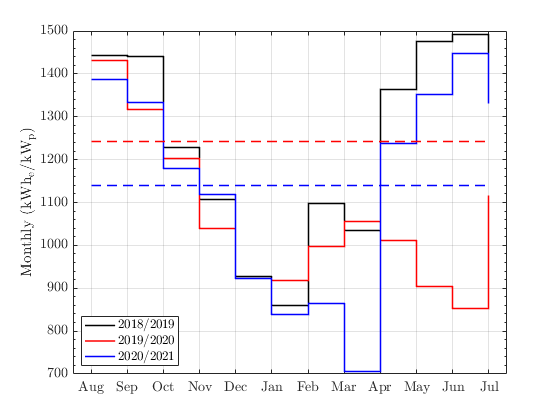

% print('-r400','-dpng','7_Mov_mean_B3_kW.png')
% print('-r400','-depsc2','7_Mov_mean_B3_kW.eps')

Days=[31 28 31 30 31 30 31 31 30 31 30 31]; 

% Month
figure
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1(1:12)/Nom_Cap*24*365,'k','Linewidth',1.5)
hold on
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1(13:24)/Nom_Cap*24*365,'r','Linewidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1(25:36)/Nom_Cap*24*365,'b','Linewidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),Y_18_19*ones(1,12)/Nom_Cap*24*365,'--k','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),Y_19_20*ones(1,12)/Nom_Cap*24*365,'--r','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),Y_20_21*ones(1,12)/Nom_Cap*24*365,'--b','LineWidth',1.5)
legend('2018/2019','2019/2020','2020/2021','location','SW','interpreter','latex')
ylabel('Monthly ($\mathrm{kWh_e/kW_p}$)','Interpreter','latex')
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

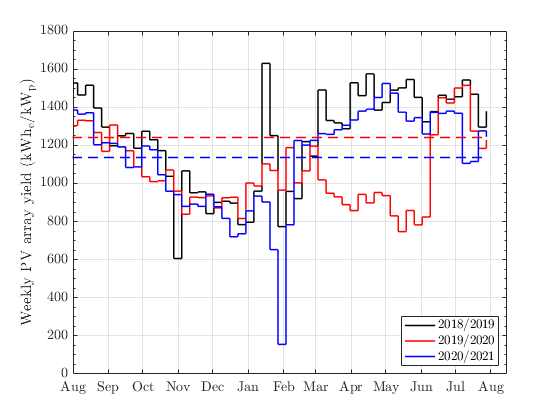

% print('-r400','-dpng','Month_B3_kW.png')
% print('-r400','-depsc2','Month_B3_kW.eps')

% Week
figure
stairs(TweeklyMean.myDatetime(1:53),TweeklyMean.Var1(1:53)/Nom_Cap*24*365,'k','LineWidth',1.5)
hold on
stairs(TweeklyMean.myDatetime(1:53),TweeklyMean.Var1(54:106)/Nom_Cap*24*365,'r','LineWidth',1.5)
stairs(TweeklyMean.myDatetime(1:53),TweeklyMean.Var1(107:159)/Nom_Cap*24*365,'b','LineWidth',1.5)
stairs(TweeklyMean.myDatetime([1 53]),[Y_18_19 Y_18_19]/Nom_Cap*24*365,'--k','LineWidth',1.5)
stairs(TweeklyMean.myDatetime([1 53]),[Y_19_20 Y_19_20]/Nom_Cap*24*365,'--r','LineWidth',1.5)
stairs(TweeklyMean.myDatetime([1 53]),[Y_20_21 Y_20_21]/Nom_Cap*24*365,'--b','LineWidth',1.5)
ylabel('Weekly PV array yield ($\mathrm{kWh_e/kW_p}$)','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('1-Aug-2018') datetime('15-Aug-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2018/2019','2019/2020','2020/2021','location','SE','interpreter','latex')

% print('-r400','-dpng','Week_B3_kW.png')
% print('-r400','-depsc2','Week_B3_kW.eps')


## Performance Comparison

% Irradiation for Horizontal surface
% https://re.jrc.ec.europa.eu/pvg_tools/en/tools.html
I_ref=[223	203	186	153	139 143	160	207	220	236	235	237]*1000./(24*Days);%[W/m2]
I_Ref=I_ref*Nom_Cap/1000

I_Ref =   303.5174  305.8992  253.1580  215.1843  189.1880  201.1200  217.7703  281.7404  309.4153  321.2112  330.5118  322.5723


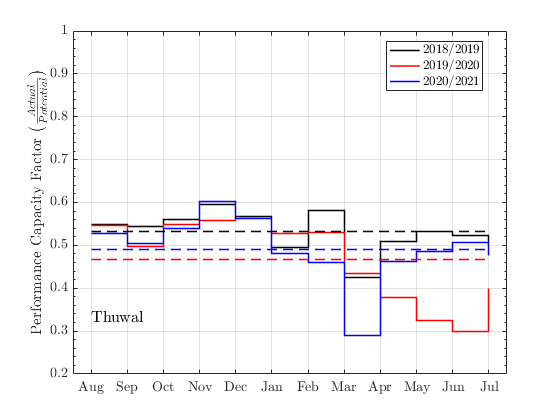

figure
stairs(reordercats(Month,cellstr(Month)'),(TmonthlyMean.Var1([1:12]))./I_Ref','k','LineWidth',1.5)
hold on
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1([13:24])./I_Ref','r','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),TmonthlyMean.Var1([25:36])./I_Ref','b','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),mean((TmonthlyMean.Var1([1:12]))./I_Ref')*ones(1,12),'--k','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),mean(TmonthlyMean.Var1([13:24])./I_Ref')*ones(1,12),'--r','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),mean(TmonthlyMean.Var1([25:36])./I_Ref')*ones(1,12),'--b','LineWidth',1.5)
legend('2018/2019','2019/2020','2020/2021','location','best','interpreter','latex')
ylabel('Performance Capacity Factor \big($\frac{Actual}{Potential}$\big)','Interpreter','latex')
text(1,0.33,'Thuwal','Color',[0 0 0],'Interpreter','latex','FontSize',16)
ylim([0.2 1])
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% Overall mean
mean([mean((TmonthlyMean.Var1([1:12]))./I_Ref')
mean(TmonthlyMean.Var1([13:24])./I_Ref')
mean(TmonthlyMean.Var1([25:36])./I_Ref')])

ans = 0.4968